# **Α1 Μέρος **

## 1o Ερώτημα

%% Load the speech signal
[y, fs] = audioread('speech.wav');

% Normalize the signal to fit in the range [-1, 1]
y = y / max(abs(y));

% Define parameters
min_value = -1;
max_value = 1;
N = 4; % Number of bits for quantization (example)

epsilon = 1e-6; % Convergence criterion for Lloyd-Max
Kmax = 100; % Maximum iterations for Lloyd-Max

%% Uniform Quantization
% Number of levels
levels_uniform = 2^N;

% Uniform quantizer
[xq_uniform, centers_uniform] = my_quantizer(y, N, min_value, max_value);

% Display results for uniform quantization
fprintf('Uniform Quantization Completed (N = %d)\n', N);

Uniform Quantization Completed (N = 4)



%% Lloyd-Max Quantization
% Number of levels
levels_lloyd = 2^N;

% Lloyd-Max quantizer
[xq_lloyd, centers_lloyd, D_lloyd] = Lloyd_Max(y, N, min_value, max_value, Kmax, epsilon);

% Display results for Lloyd-Max quantization
fprintf('Lloyd-Max Quantization Completed (N = %d)\n', N);

Lloyd-Max Quantization Completed (N = 4)


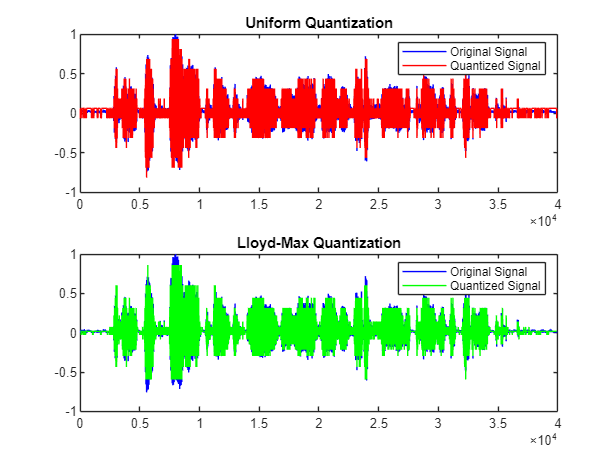


%% Plot Quantized Outputs
figure;
subplot(2, 1, 1);
plot(y, 'b'); hold on; plot(xq_uniform, 'r');
title('Uniform Quantization');
legend('Original Signal', 'Quantized Signal');

title('Uniform Quantization');

subplot(2, 1, 2);
plot(y, 'b'); hold on; plot(xq_lloyd, 'g');
title('Lloyd-Max Quantization');
legend('Original Signal', 'Quantized Signal');


%% Function Definitions

function [xq, centers] = my_quantizer(x, N, min_value, max_value)
    levels = 2^N;
    delta = (max_value - min_value) / levels;
    centers = linspace(min_value + delta / 2, max_value - delta / 2, levels);

    % Quantize signal
    xq_indices = min(max(round((x - min_value) / delta + 0.5), 1), levels);
    xq = centers(xq_indices);
end

function [xq, centers, D] = Lloyd_Max(x, N, min_value, max_value, Kmax, epsilon)
    levels = 2^N;

    % Initialize centers uniformly
    delta = (max_value - min_value) / levels;
    centers = linspace(min_value + delta / 2, max_value - delta / 2, levels)';

    % Initialize distortion D
    D = Inf;

    for k = 1:Kmax
        % Compute thresholds
        thresholds = [(min_value + centers(1)) / 2; (centers(1:end-1) + centers(2:end)) / 2; (centers(end) + max_value) / 2];

        % Quantize signal
        % Use broadcasting for pairwise distance computation
        [~, xq_indices] = min(abs(x - centers'), [], 2);
        xq = centers(xq_indices);

        % Compute distortion
        D_new = mean((x - xq).^2);
        if k > 1 && abs(D_new - D) < epsilon
            break;
        end
        D = D_new;

        % Update centers
        for i = 1:levels
            if sum(xq_indices == i) > 0
                centers(i) = mean(x(xq_indices == i));
            end
        end
    end
end




## **2ο Ερώτημα**

**1o υποερώτημα**

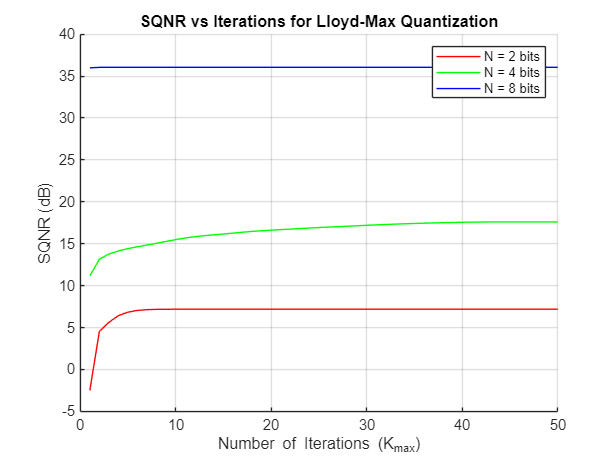

%% Load the speech signal
[y, fs] = audioread('speech.wav');

% Normalize the signal to fit in the range [-1, 1]
y = y / max(abs(y));

% Define parameters
min_value = -1;
max_value = 1;
N_values = [2, 4, 8]; % Different bit depths
epsilon = 1e-6; % Convergence criterion for Lloyd-Max
Kmax_values = 1:50; % Number of iterations to test

%% Lloyd-Max Quantization SQNR Analysis
SQNR_results = zeros(length(N_values), length(Kmax_values));

for n_idx = 1:length(N_values)
    N = N_values(n_idx);
    levels = 2^N;

    % Initialize centers uniformly for Lloyd-Max
    delta = (max_value - min_value) / levels;
    centers = linspace(min_value + delta / 2, max_value - delta / 2, levels)';

    for k_idx = 1:length(Kmax_values)
        Kmax = Kmax_values(k_idx);

        % Lloyd-Max quantizer
        centers_temp = centers;
        D = Inf;

        for k = 1:Kmax
            % Compute thresholds
            thresholds = [(min_value + centers_temp(1)) / 2; (centers_temp(1:end-1) + centers_temp(2:end)) / 2; (centers_temp(end) + max_value) / 2];

            % Quantize signal
            [~, xq_indices] = min(abs(y - centers_temp'), [], 2);
            xq = centers_temp(xq_indices);

            % Compute distortion
            D_new = mean((y - xq).^2);
            if abs(D_new - D) < epsilon
                break;
            end
            D = D_new;

            % Update centers
            for i = 1:levels
                if sum(xq_indices == i) > 0
                    centers_temp(i) = mean(y(xq_indices == i));
                end
            end
        end

        % Compute SQNR
        SQNR_results(n_idx, k_idx) = 10 * log10(mean(y.^2) / mean((y - xq).^2));
    end
end

%% Plot SQNR vs Iterations
figure;
hold on;
colors = ['r', 'g', 'b'];
for n_idx = 1:length(N_values)
    plot(Kmax_values, SQNR_results(n_idx, :), 'DisplayName', sprintf('N = %d bits', N_values(n_idx)), 'Color', colors(n_idx));
end
xlabel('Number of Iterations (K_{max})');
ylabel('SQNR (dB)');
title('SQNR vs Iterations for Lloyd-Max Quantization');
legend('show');
grid on;

#### 2ο υποερώτημα

%% Load the speech signal
[y, fs] = audioread('speech.wav');

% Normalize the signal to fit in the range [-1, 1]
y = y(:) / max(abs(y)); % Ensure column vector

% Define parameters
min_value = -1;
max_value = 1;
N_values = [2, 4, 8]; % Different bit depths
epsilon = 1e-6; % Convergence criterion for Lloyd-Max
Kmax = 50; % Maximum iterations for Lloyd-Max

%% Initialize SQNR Results
SQNR_uniform = zeros(1, length(N_values));
SQNR_lloyd = zeros(1, length(N_values));

for n_idx = 1:length(N_values)
    N = N_values(n_idx);

    %% Uniform Quantization
    [xq_uniform, centers_uniform] = my_quantizer(y, N, min_value, max_value);
    xq_uniform = reshape(xq_uniform, size(y)); % Match dimensions
    SQNR_uniform(n_idx) = 10 * log10(mean(y.^2) / mean((y - xq_uniform).^2));

    %% Lloyd-Max Quantization
    [xq_lloyd, centers_lloyd, ~] = Lloyd_Max(y, N, min_value, max_value, Kmax, epsilon);
    xq_lloyd = reshape(xq_lloyd, size(y)); % Match dimensions
    SQNR_lloyd(n_idx) = 10 * log10(mean(y.^2) / mean((y - xq_lloyd).^2));
end


fprintf('Comparison of SQNR (in dB):\n');

Comparison of SQNR (in dB):


for n_idx = 1:length(N_values)
    fprintf('N = %d bits: Uniform = %.2f dB, Lloyd-Max = %.2f dB\n', ...
        N_values(n_idx), SQNR_uniform(n_idx), SQNR_lloyd(n_idx));
end

N = 2 bits: Uniform = -2.48 dB, Lloyd-Max = 7.19 dB
N = 4 bits: Uniform = 11.17 dB, Lloyd-Max = 17.59 dB
N = 8 bits: Uniform = 35.97 dB, Lloyd-Max = 36.03 dB


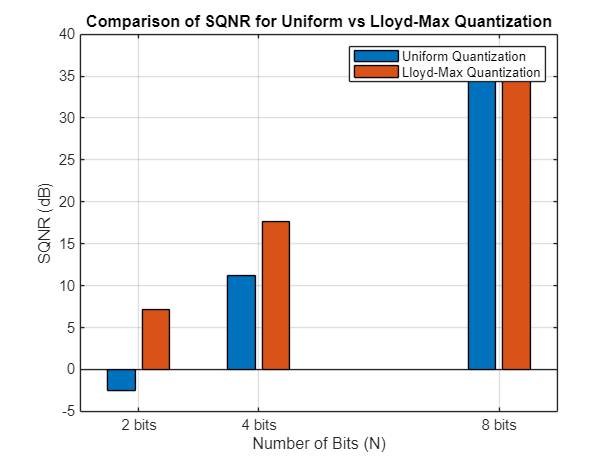



figure;
bar(N_values, [SQNR_uniform; SQNR_lloyd]');
hold on;
set(gca, 'xticklabel', arrayfun(@(x) sprintf('%d bits', x), N_values, 'UniformOutput', false));
legend('Uniform Quantization', 'Lloyd-Max Quantization');
title('Comparison of SQNR for Uniform vs Lloyd-Max Quantization');
ylabel('SQNR (dB)');
xlabel('Number of Bits (N)');
grid on;



function [xq, centers] = my_quantizer2(x, N, min_value, max_value)
    levels = 2^N;
    delta = (max_value - min_value) / levels;
    centers = linspace(min_value + delta / 2, max_value - delta / 2, levels);

    
    x_clipped = max(min(x, max_value), min_value);

    % Quantize signal
    xq_indices = min(max(round((x_clipped - min_value) / delta + 0.5), 1), levels);
    xq = centers(xq_indices);
end

function [xq, centers, D] = Lloyd_Max2(x, N, min_value, max_value, Kmax, epsilon)
    levels = 2^N;

   
    delta = (max_value - min_value) / levels;
    centers = linspace(min_value + delta / 2, max_value - delta / 2, levels)';

    
    D = Inf;

    for k = 1:Kmax
        
        thresholds = [(min_value + centers(1)) / 2; (centers(1:end-1) + centers(2:end)) / 2; (centers(end) + max_value) / 2];

       
        [~, xq_indices] = min(abs(x - centers'), [], 2);
        xq = centers(xq_indices);

       
        D_new = mean((x - xq).^2);
        if k > 1 && abs(D_new - D) < epsilon
            break;
        end
        D = D_new;

        % Update centers
        for i = 1:levels
            if sum(xq_indices == i) > 0
                centers(i) = mean(x(xq_indices == i));
            end
        end
    end
end








#### 3o Υποερώτημα

%% Load the speech signal
[y, fs] = audioread('speech.wav');

% Normalize the signal to fit in the range [-1, 1]
y = y(:) / max(abs(y)); 

% Define parameters
min_value = -1;
max_value = 1;
N_values = [2, 4, 8]; 
epsilon = 1e-6; 
Kmax = 50; 

%% Play and Compare Waveforms
for n_idx = 1:length(N_values)
    N = N_values(n_idx);
    
    %% Uniform Quantization
    [xq_uniform, ~] = my_quantizer(y, N, min_value, max_value);

    %% Lloyd-Max Quantization
    [xq_lloyd, ~, ~] = Lloyd_Max(y, N, min_value, max_value, Kmax, epsilon);
    
    %% Play Sounds
    fprintf('Playing sounds for N = %d bits...\n', N);
    
    % Play original signal
    fprintf('Playing Original Signal...\n');
    sound(y, fs);
    pause(length(y) / fs + 1); % Wait for sound to finish
    
    % Play uniform quantized signal
    fprintf('Playing Uniform Quantized Signal...\n');
    sound(xq_uniform, fs);
    pause(length(xq_uniform) / fs + 1); % Wait for sound to finish
    
    % Play Lloyd-Max quantized signal
    fprintf('Playing Lloyd-Max Quantized Signal...\n');
    sound(xq_lloyd, fs);
    pause(length(xq_lloyd) / fs + 1); % Wait for sound to finish
end

Playing sounds for N = 2 bits...


Playing Original Signal...


Playing Uniform Quantized Signal...


Playing Lloyd-Max Quantized Signal...


Playing sounds for N = 4 bits...


Playing Original Signal...


Playing Uniform Quantized Signal...


Playing Lloyd-Max Quantized Signal...


Playing sounds for N = 8 bits...


Playing Original Signal...


Playing Uniform Quantized Signal...


Playing Lloyd-Max Quantized Signal...


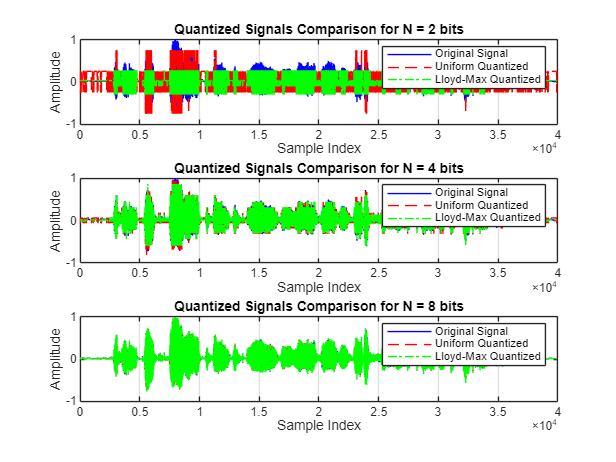


%% Plot and Compare Waveforms
figure;

for n_idx = 1:length(N_values)
    N = N_values(n_idx);
    
    %% Uniform Quantization
    [xq_uniform, ~] = my_quantizer(y, N, min_value, max_value);

    %% Lloyd-Max Quantization
    [xq_lloyd, ~, ~] = Lloyd_Max(y, N, min_value, max_value, Kmax, epsilon);
    
    %% Plot Results
    subplot(length(N_values), 1, n_idx);
    plot(y, 'b', 'DisplayName', 'Original Signal'); hold on;
    plot(xq_uniform, 'r--', 'DisplayName', 'Uniform Quantized');
    plot(xq_lloyd, 'g-.', 'DisplayName', 'Lloyd-Max Quantized');
    title(sprintf('Quantized Signals Comparison for N = %d bits', N));
    legend('show');
    xlabel('Sample Index');
    ylabel('Amplitude');
    grid on;
end

#### 4o Υποερώτημα

%% Load the speech signal
[y, fs] = audioread('speech.wav');

% Normalize the signal to fit in the range [-1, 1]
y = y(:) / max(abs(y)); % Ensure column vector

% Define parameters
min_value = -1;
max_value = 1;
N_values = [2, 4, 8]; 
epsilon = 1e-6; 
Kmax = 50; 

%% Initialize MSE Results
MSE_uniform = zeros(1, length(N_values));
MSE_lloyd = zeros(1, length(N_values));

for n_idx = 1:length(N_values)
    N = N_values(n_idx);

    %% Uniform Quantization
    [xq_uniform, ~] = my_quantizer(y, N, min_value, max_value);
    xq_uniform = reshape(xq_uniform, size(y)); % Match dimensions
    MSE_uniform(n_idx) = mean((y - xq_uniform).^2);

    %% Lloyd-Max Quantization
    [xq_lloyd, ~, ~] = Lloyd_Max(y, N, min_value, max_value, Kmax, epsilon);
    xq_lloyd = reshape(xq_lloyd, size(y)); % Match dimensions
    MSE_lloyd(n_idx) = mean((y - xq_lloyd).^2);
end

%% Display Results
fprintf('Comparison of MSE:\n');

Comparison of MSE:


for n_idx = 1:length(N_values)
    fprintf('N = %d bits: Uniform = %.6f, Lloyd-Max = %.6f\n', ...
        N_values(n_idx), MSE_uniform(n_idx), MSE_lloyd(n_idx));
end

N = 2 bits: Uniform = 0.035736, Lloyd-Max = 0.003850
N = 4 bits: Uniform = 0.001542, Lloyd-Max = 0.000351
N = 8 bits: Uniform = 0.000005, Lloyd-Max = 0.000005


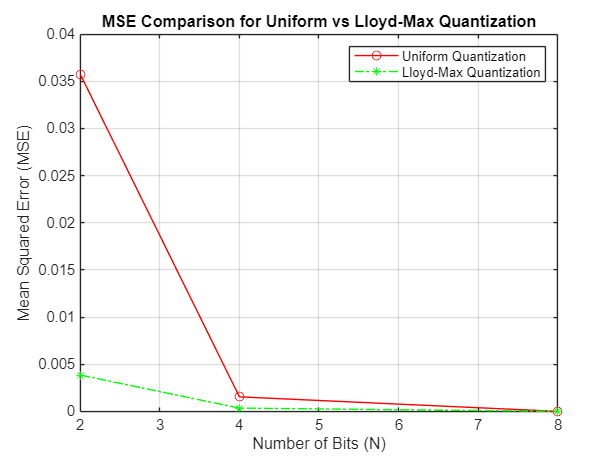


%% Plot MSE Comparison
figure;
plot(N_values, MSE_uniform, 'r-o', 'DisplayName', 'Uniform Quantization'); hold on;
plot(N_values, MSE_lloyd, 'g-.*', 'DisplayName', 'Lloyd-Max Quantization');
title('MSE Comparison for Uniform vs Lloyd-Max Quantization');
xlabel('Number of Bits (N)');
ylabel('Mean Squared Error (MSE)');
legend('show');
grid on;